Post processing of VAL Tests

This program process the mechanical data obtained from Instron Dynamic Tester

clc
close all
clear variables
% close all
% Theoretical slope (programmed increment)
dFmax_programmed = 1; % N per cycle
thresh_multi = 3; % This is threshold multiplier for determining load segments of each SD or CSV file

## GR250 Tests


% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251114 Test15\Take-2\VALIR_GR250\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251114 Test15\Take-1\VALIR_GR250\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251114 Test14\Take-1\VALIR_GR250\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_7\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_6\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_5\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_4\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_3\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_2\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251113 Test13\Take_1\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251105 Test10\Take 1\Test1'];

% 'Test12 20251112\Take2\VALIR_GR250_Test12_take2\Test1'];
% 'Test12 20251112\Take1\VALIR_GR250_Test12_take1\Test1'];

folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251106 Test11\Test11_take1 BlockLoad_GR250\Test1']

folderPath = 'C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251106 Test11\Test11_take1 BlockLoad_GR250\Test1'


% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\GR250_VAL\20251105 Test10\Take 1\Test1'];

% 'Test9 20251103\VAL_GR250_Test9_take2\Test1'];
% 'Test8 20251103\VAL_GR250_Test8_take4\Test1'];
% 'Test8 20251103\VAL_GR250_Test8_take3\Test1'];
% 'Test8 20251103\VAL_GR250_Test8_take2\Test1'];
% 'Test8 20251103\VAL_GR250_Test8_take1\Test1'];
% 'Test7 20251103\VAL_GR250_Test7_take1\Test1'];
% 'Test5 20251022\VAL_GR250_Test5_take4\Test1'];

## SS304 Tests

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_BL_Test-2_Take-1\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_BL_Test-1_Take-2\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_BL_Test-1_Take-1\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-3_Take-3\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-3_Take-2\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-3_Take-1\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-14\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-13\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-12\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-11\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-10\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-9\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-8\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-7\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-5\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-4\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-3\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-2\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251118\20251118_SS304_Test-2_Take-1\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251117\20251117 SS304-Test-1-Take-5\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251117\20251117 SS304-Test-1-Take-4\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251117\20251117 SS304-Test-1-Take-3\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251117\20251117 SS304-Test-1-Take-2\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251117\20251117 SS304_Test-1-take-1\VALIR_SS304\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-19_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-18_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-17_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-16_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-15_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-14_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-13_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-12_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-11_R0d1\VALIR_SS304\Test1'];
% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\SS304_TestX01_take-10_R0d1\VALIR_SS304\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\'...
% 'SS304_TestX01_take-9_R0d1\VALIR_SS304\Test1']; % Conducted on 17-Nov-2025
% 'SS304_TestX01_take-7_R0d03\VALIR_SS304\Test1'];
% 'SS304_TestX01_take-6_R0d03\VALIR_SS304\Test1'];
% 'SS304_TestX01_take-5_R0d03\VALIR_SS304\Test1'];
% 'SS304_TestX01_R0d1_take4\VALIR_SS304\Test1'];
% 'SS304_TestX01_R0d1_take3\VALIR_SS304\Test1'];
% 'SS304_TestX01_R0d05_take2\VALIR_SS304\Test1'];

% 'SS304_TestX01_R0d05_take1\VALIR_SS304\Test1'];

% '20251117_SS304_Test-1-take-1\SS304-Test-1-Take-1\VALIR_SS304\Test1'];

% folderPath = ['C:\Users\mo170\OneDrive - The University of Waikato\PhD\Experiments\SS304_VAL\20251114\Test-1 Take-01\Test1'];




## Extracting Test Name from the file path and name


fileName = 'Test1.steps.tracking.csv';
% fileName = 'combinedCSV.xlsx';




% Extract "TestXX" and "TakeYY" in any separator format
tokens = regexp(folderPath, '(Test[-_ ]?\d+).*?(Take[-_ ]?\d+)', ...
                'tokens', 'ignorecase');

if ~isempty(tokens)
    parts = tokens{1};

    % Remove spaces, underscores, and dashes → standardise numbers
    cleanTest = regexprep(parts{1}, '[-_ ]', '');
    cleanTake = regexprep(parts{2}, '[-_ ]', '');

    % Final standardised format → TestXX-TakeYY
    testName = [cleanTest '-' cleanTake];
else
    testName = 'UnknownTest';
end


## Extracting Data from the Instron Data file

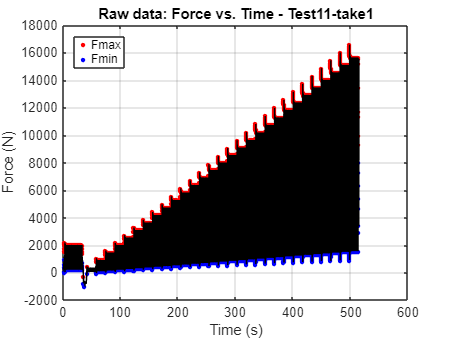

fileWithPath = fullfile(folderPath, fileName);  % Combines path and filename safely
data = readmatrix(fileWithPath);

time_meca = data(1:end,1);
force = data(1:end,8)*1000; % Convert load from kN to N
position = data(1:end,7); %

% Separating high and low peaks
minProminence = 0.03 * max(force); % Minimum peak prominence
[highs, locs_highs] = findpeaks(force, 'MinPeakProminence', minProminence);
Time_highs = time_meca(locs_highs);

[lows, locs_lows] = findpeaks(-force, 'MinPeakProminence', minProminence);
Time_lows = time_meca(locs_lows);
lows = -lows;

% plot Fhighs and Flows
figure;
plot(Time_highs,highs, '.r',MarkerSize=10);
title(['Raw data: Force vs. Time - ', testName]);
hold on
plot(Time_lows, lows, '.b',MarkerSize=10)
plot(time_meca,force,'-k', LineWidth=0.5)
grid on
legend ('Fmax','Fmin', 'location','northwest')
xlabel('Time (s)')
ylabel('Force (N)')

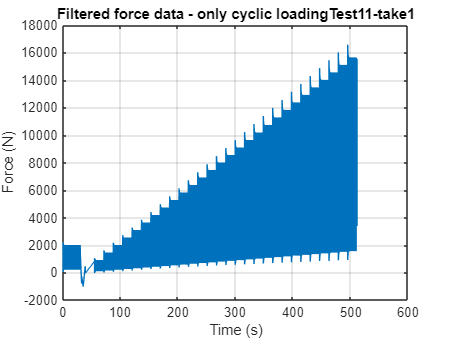

% --- Save figure ---
figTitle = get(get(gca, 'Title'), 'String');
figureName = regexprep(figTitle, '[^\w\s-]', '');  % remove special chars (like :)
figureName = strrep(figureName, ' ', '_');           % replace spaces with underscores
saveas(gcf, fullfile(folderPath, [figureName '.fig']));


% Combine and sort extrema
all_locs = [locs_highs; locs_lows; 1; length(force)];
all_vals = [highs; lows; force(1); force(end)];
is_max = [true(size(locs_highs)); false(size(locs_lows)); force(1) > force(2); force(end) > force(end-1)];
[all_locs_sorted, sort_idx] = sort(all_locs);
all_vals_sorted = all_vals(sort_idx);
is_max_sorted = is_max(sort_idx);

% Enforce zig-zag alternation
zigzag_idx = all_locs_sorted(1);
zigzag_vals = all_vals_sorted(1);
last_type = is_max_sorted(1);
for i = 2:length(all_locs_sorted)
    if is_max_sorted(i) ~= last_type
        zigzag_idx(end+1) = all_locs_sorted(i);
        zigzag_vals(end+1) = all_vals_sorted(i);
        last_type = is_max_sorted(i);
    end
end

F_filtered = force(zigzag_idx(2:end-1)); % starting from 2 because the first point is from the ramp step of the testing and it is not in the cyclic loading step.
T_filtered = time_meca(zigzag_idx(2:end-1));
T_filtered = T_filtered - T_filtered(1);

figure; plot (T_filtered,F_filtered); grid on
title(['Filtered force data - only cyclic loading', testName]);
xlabel('Time (s)')
ylabel('Force (N)')

% --- Save figure ---
figTitle = get(get(gca, 'Title'), 'String');
figureName = regexprep(figTitle, '[^\w\s-]', '');  % remove special chars (like :)
figureName = strrep(figureName, ' ', '_');           % replace spaces with underscores
saveas(gcf, fullfile(folderPath, [figureName '.fig']));

[Fhighs, locs_highs] = findpeaks(F_filtered);
t_highs = T_filtered(locs_highs);

N = length(t_highs);
x = round(0.4*N);
y = round(0.45*N);
T_exp = mean(diff(t_highs(x:y))); % Loading time period (T)
LF_exp = 1/T_exp;
fprintf('Loading frequency as per the experimental data: %0.2f Hz\n',LF_exp);

Loading frequency as per the experimental data: 19.08 Hz


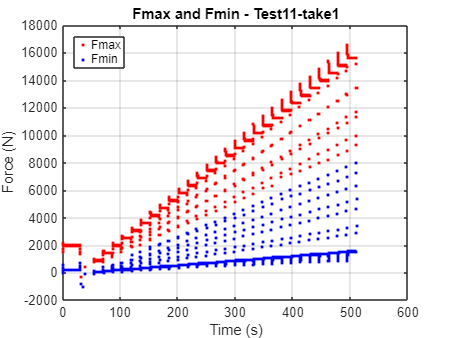


[Flows, locs_lows] = findpeaks(-F_filtered);
Flows = -1 * Flows;
t_lows = T_filtered(locs_lows);
lows_spacing = diff(locs_lows);

figure;
plot(t_highs,Fhighs, '.r');
title(['Fmax and Fmin - ', testName]);
hold on
plot(t_lows, Flows, '.b')
grid on
legend ('Fmax','Fmin', 'location','northwest')
xlabel('Time (s)')
ylabel('Force (N)')

% --- Save figure ---
figTitle = get(get(gca, 'Title'), 'String');
figureName = regexprep(figTitle, '[^\w\s-]', '');  % remove special chars (like :)
figureName = strrep(figureName, ' ', '_');           % replace spaces with underscores
saveas(gcf, fullfile(folderPath, [figureName '.fig']));


% Check length difference
lenDiff = abs(length(Fhighs) - length(Flows));

if lenDiff > 1
    error('Length difference between Fhigh (%d) and Flows (%d) exceeds 1.', length(Fhighs), length(Flows));
else
    % Truncate the longer vector to match the shorter one
    minLen = min(length(Fhighs), length(Flows));
    Fhighs = Fhighs(1:minLen);
    Flows = Flows(1:minLen);
    t_lows = t_lows(1:minLen);
    t_highs = t_highs(1:minLen);
end


### **Processing position data**

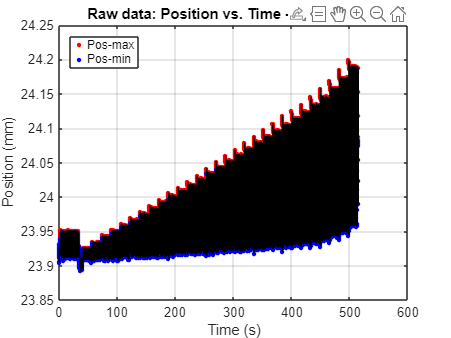

position = data(1:end,7); %

% Separating high and low peaks
pos_minProminence = 0.00003 * max(position); % Minimum peak prominence
[pos_highs, pos_locs_highs] = findpeaks(position, 'MinPeakProminence', pos_minProminence);
pos_Time_highs = time_meca(pos_locs_highs);

[pos_lows, pos_locs_lows] = findpeaks(-position, 'MinPeakProminence', pos_minProminence);
pos_Time_lows = time_meca(pos_locs_lows);
pos_lows = -pos_lows;

% plot Fhighs and Flows
figure;
plot(pos_Time_highs,pos_highs, '.r',MarkerSize=10);
title(['Raw data: Position vs. Time - ', testName]);
hold on
plot(pos_Time_lows, pos_lows, '.b',MarkerSize=10)
plot(time_meca,position,'-k', LineWidth=0.5)
grid on
legend ('Pos-max','Pos-min', 'location','northwest')
xlabel('Time (s)')
ylabel('Position (mm)')

% --- Save figure ---
figTitle = get(get(gca, 'Title'), 'String');
figureName = regexprep(figTitle, '[^\w\s-]', '');  % remove special chars (like :)
figureName = strrep(figureName, ' ', '_');           % replace spaces with underscores
saveas(gcf, fullfile(folderPath, [figureName '.fig']));

Comparing the programmed Fmax increment/cycle with the Fmax increment/cycle achieved from the experimental data

%% Comparing the programmed Fmax increment/cycle with the Fmax increment/cycle achieved from the experimental data
cycleNum = (1:length(Fhighs))';

% Linear regression of Fhighs vs. cycle number
p = polyfit(cycleNum, Fhighs, 1);
dFmax_exp = p(1);

% Deviation between experimental and theoretical slope
deviation = (dFmax_exp - dFmax_programmed) / dFmax_programmed * 100;

fprintf('Programmed Fmax Increment:   %.3f N/cycle\n', dFmax_programmed);
fprintf('Experimental Fmax Increment: %.3f N/cycle\n', dFmax_exp);
fprintf('Deviation:          %.2f %%\n', deviation);

% --- Plot comparison ---
figure;
plot(cycleNum, Fhighs, '.k', 'DisplayName', 'Measured F_{max}');
hold on;
plot(cycleNum, polyval(p, cycleNum), '-r', 'LineWidth', 1.5, 'DisplayName', sprintf('Fit (%.2f N/cycle)', dFmax_exp));
plot(cycleNum, dFmax_programmed*cycleNum + Fhighs(1), '--b', 'LineWidth', 1.5, 'DisplayName', sprintf('Programmed (%.2f N/cycle)', dFmax_programmed));
xlabel('Cycle number');
ylabel('F_{max} (N)');
title('Comparison of Experimental and Programmed F_{max} Increment');
legend('Location', 'northwest');
grid on;

Force ratio using linear regression

%% Force ratio using linear regression
% close all
window_fraction = 0.98;   % fraction of total time span
offset    = 0; %round(T_filtered(end)*0.0,0);       % offset in seconds, if needed

% Mid time
t_mid = (T_filtered(1) + T_filtered(end)) / 2 + offset;

% Half window in time
half_window_time = window_fraction * (T_filtered(end) - T_filtered(1)) / 2;

% Find indices of points within the window
start_idx = find(T_filtered >= t_mid - half_window_time, 1, 'first');
end_idx   = find(T_filtered <= t_mid + half_window_time, 1, 'last');
end_idx = fix(end_idx/2);

F_high = Fhighs(start_idx:end_idx);
F_low = Flows(start_idx:end_idx);
Time_low = t_lows(start_idx:end_idx);
Time_high= t_highs(start_idx:end_idx);

% Linear Regression Fits
f_high = fit(Time_high(:), F_high(:), 'poly1');
f_low  = fit(Time_low(:),  F_low(:),  'poly1');

% Evaluate fits
yfit_high = feval(f_high, Time_high);
yfit_low  = feval(f_low,  Time_low);

% Compute Force Ratio
Force_Ratio = f_low.p1 / f_high.p1

% ---------------------- Create Figure ----------------------
figure('Position',[200 150 900 600]);

% --- Top Plot (Main Axes) ---
ax1 = axes('Position',[0.1 0.35 0.85 0.55]); % [x y width height]
hold(ax1,'on'); grid(ax1,'on');

% Plot original and selected data
plot(ax1, T_filtered, F_filtered, 'k.', 'DisplayName','Original Force');
plot(ax1, Time_high, F_high, 'ro', 'DisplayName','Force high (selected)');
plot(ax1, Time_low,  F_low,  'bo', 'DisplayName','Force low (selected)');

% Plot fits
plot(ax1, Time_high, yfit_high, 'g-', 'LineWidth',2.5, 'DisplayName','Fit high');
plot(ax1, Time_low,  yfit_low,  'm-', 'LineWidth',2,  'DisplayName','Fit low');

legend(ax1,'Location','northwest');
title(ax1,['Force vs. Time with Linear Fits - ', testName]);
xlabel(ax1,'Time (s)');
ylabel(ax1,'Force (N)');

% Mid-point line
xline(ax1, t_mid, '--c', 'LineWidth', 1.5, 'HandleVisibility','off');
yl = ylim(ax1);
text(t_mid, yl(2), 'Mid time', 'Rotation', 90, ...
    'VerticalAlignment','bottom','HorizontalAlignment','right', ...
    'FontSize',9,'Color','c','Parent',ax1);

% ---------------------- Bottom Text Area ----------------------
ax2 = axes('Position',[0.1 0.05 0.85 0.25]); % lower area for text
axis(ax2,'off'); % hide axes

% Prepare text lines (formatted with LaTeX style)
eq1 = sprintf('$F_{high}(t) = %.2f\\,t + %.2f$', f_high.p1, f_high.p2);
eq2 = sprintf('$F_{low}(t) = %.2f\\,t + %.2f$',  f_low.p1,  f_low.p2);
Rtxt = sprintf('$R = F_{low}/F_{high} = %.3f$', Force_Ratio);
Wtxt = sprintf('Window fraction: $\\pm%.1f\\,\\%%$', window_fraction*100);
Otxt = sprintf('Mid-point offset: $%.2f\\,\\mathrm{s}$', offset);

% Combine in vertically aligned text
text(0.05, 0.75, eq1, 'Interpreter','latex', 'FontSize',14, 'Color','g', 'Parent',ax2);
text(0.05, 0.55, eq2, 'Interpreter','latex', 'FontSize',14, 'Color','m', 'Parent',ax2);
text(0.05, 0.35,  Rtxt, 'Interpreter','latex', 'FontSize',14, 'Color','k', 'Parent',ax2);
text(0.05, 0.15, Wtxt, 'Interpreter','latex', 'FontSize',11, 'Color','k', 'Parent',ax2);
text(0.05, 0.00, Otxt, 'Interpreter','latex', 'FontSize',11, 'Color','k', 'Parent',ax2);

% --- Save figure ---
figTitle = get(get(ax1, 'Title'), 'String');
figureName = regexprep(figTitle, '[^\w\s-]', '');  % remove special chars (like :)
figureName = strrep(figureName, ' ', '_');           % replace spaces with underscores
saveas(gcf, fullfile(folderPath, [figureName '.fig']));

Find the R for each load step (CSV or Sampled Data Step) separately

% --- Step 1: Compute time differences between consecutive points ---
dtLows = diff(t_lows);

% --- Step 2: Automatically find "large jumps" ---
% You can tune this threshold depending on your data
threshold = thresh_multi * median(dtLows);  % For example, 5× median time step
stepChangeIdxLows = find(dtLows > threshold);

% --- Step 3: Determine segment boundaries ---
segmentStartLows = [1; stepChangeIdxLows + 1];
segmentEndLows = [stepChangeIdxLows; length(t_lows)];

% --- Step 4: Extract segments into cell arrays ---
numSteps = numel(segmentStartLows);
maxLen = max(segmentEndLows - segmentStartLows + 1);

flowSteps = NaN(numSteps, maxLen);
timeStepsLow = NaN(numSteps, maxLen);
fhighSteps = NaN(numSteps, maxLen);
timeStepsHigh = NaN(numSteps, maxLen);

for i = 1:numSteps
    idx = segmentStartLows(i):segmentEndLows(i);
    % Remove last point to exclude undershoot (if at least 2 points exist)
    if numel(idx) > 1
        idx(end) = [];
    end
    len = numel(idx);

    % --- Low data ---
    flowSteps(i, 1:len) = Flows(idx);
    timeStepsLow(i, 1:len) = t_lows(idx);

    % --- High data ---
    fhighSteps(i, 1:len)     = Fhighs(idx);
    timeStepsHigh(i, 1:len)  = t_highs(idx);
end


%% --- Step 6: Linear regression for each segment (middle 80%) ---

R_values = NaN(numSteps,1);   % Ratio of slopes (Flow / Fhigh)
slopes_low = NaN(numSteps,1);
slopes_high = NaN(numSteps,1);
dFmax_exp  = NaN(numSteps,1);
devIncrement = NaN(numSteps,1);

figure; hold on; grid on;
title(['Segments Linear Fits - ', testName]);
xlabel('Time (s)');
ylabel('Force (N)');

for i = 1:numSteps
    % Extract non-NaN data
    tL = timeStepsLow(i, :);
    fL = flowSteps(i, :);
    tH = timeStepsHigh(i, :);
    fH = fhighSteps(i, :);

    validIdxL = ~isnan(tL) & ~isnan(fL);
    validIdxH = ~isnan(tH) & ~isnan(fH);

    tL = tL(validIdxL);
    fL = fL(validIdxL);
    tH = tH(validIdxH);
    fH = fH(validIdxH);

    if numel(tL) < 3 || numel(tH) < 3
        continue;  % Skip if insufficient data
    end

    % Middle 75% subset --- to avoid including under- and overshoot data points
    nL = numel(tL);
    nH = numel(tH);
    idxRange = round(0.3*nL) : round(0.9*nL);
    % idxRange = round(0.1*nH) : round(0.9*nH);

    tL_mid = tL(idxRange);
    fL_mid = fL(idxRange);
    tH_mid = tH(idxRange);
    fH_mid = fH(idxRange);

    % --- Linear regression (1st order polynomial fit) ---
    pL = polyfit(tL_mid, fL_mid, 1);
    pH = polyfit(tH_mid, fH_mid, 1);

    % when maximum force is increasing per cycle
    slopes_low(i) = pL(1);
    slopes_high(i) = pH(1);

    % y = i
    % AA = pH(1)
    
    % when maximum force is constant
    if pH(1) < 10
    slopes_low(i) = pL(2);
    slopes_high(i) = pH(2);
    x = i
    end

    % --- Calculate R (slope ratio) ---
    R_values(i) = slopes_low(i) / slopes_high(i);

    % --- Plot raw data ---
    plot(tL, fL, '.b', 'LineWidth', .2, 'DisplayName', 'Flows');
    plot(tH, fH, '.r', 'LineWidth', .2, 'DisplayName', 'Fhighs');

    % --- Plot fitted lines ---
    yfitL = polyval(pL, tL);
    yfitH = polyval(pH, tH);
    plot(tL, yfitL, '--cy', 'LineWidth', 2);
    plot(tH, yfitH, '--k', 'LineWidth', 2);

    % --- Linear regression (1st order polynomial fit) for Fmax Increment Per cycle
    % Linear regression of Fhighs vs. cycle number
    p = polyfit(1:length(fH_mid), fH_mid, 1);
    dFmax_exp (i) = p(1); % Increment in Fmax/cycle from the experimental data

    % Deviation of experimental Fmax Increment/cycle in each segment from the programmed value
    devIncrement(i) = (dFmax_exp(i) - dFmax_programmed) / dFmax_programmed * 100;


    % --- Annotate R and Fmax increment value ---
    x_mid = mean([tL(1), tL(end)]);
    y_max = max([fL(:); fH(:)]);
    text(x_mid, y_max, sprintf('R = %.3f', R_values(i)), ...
        'FontSize', 11, 'HorizontalAlignment', 'right');
    % R_values(i)
end

legend({'Flows','Fhighs','Flows Fit','Fhighs Fit'}, 'Location', 'northwest');

hold off;

% --- Save figure ---
figTitle = get(get(gca, 'Title'), 'String');
figureName = regexprep(figTitle, '[^\w\s-]', '');  % remove special chars (like :)
figureName = strrep(figureName, ' ', '_');           % replace spaces with underscores
saveas(gcf, fullfile(folderPath, [figureName '.fig']));

%----- Slopes of segments, their ratio R, deltaFmax
% T = table((1:numSteps)', ...
%     round(slopes_low, 2), ...
%     round(slopes_high, 2), ...
%     round(R_values, 3), ...
%     round(dFmax_exp, 2), ...
%     round(devIncrement, 2), ...
%     'VariableNames', {'Segment','Slope Low (N)','Slope High (N)','R','DeltaFmax/cycle (N)','Deviation (%)'});
% 
% % Compute mean values
% mean_R_exp = round(mean(R_values, 'omitnan'),3);
% mean_dFmax_exp = round(mean(dFmax_exp, 'omitnan'),2);
% 
% T(end+1,:) = {NaN, NaN, NaN, mean_R_exp, mean_dFmax_exp, NaN};

T = table((1:numSteps)', ...
    round(R_values, 3), ...
    round(dFmax_exp, 2), ...
    'VariableNames', {'Segment','R','dFmax/cycle (N)'}); %,'Deviation (%)'});
    % round(devIncrement, 2), ...

% Compute mean values
% mean_R_exp = round(mean(R_values, 'omitnan'),5);
% mean_dFmax_exp = round(mean(dFmax_exp, 'omitnan'),5);
mean_R_exp = (mean(R_values, 'omitnan'))
mean_dFmax_exp = (mean(dFmax_exp, 'omitnan'))

T(end+1,:) = {NaN, mean_R_exp, mean_dFmax_exp}; %, NaN};
disp(T)

tableName = ['Summary_Table - ' testName];
fig = uifigure('Name', tableName, 'Color', 'k', 'Position', [100 200 700 700]);
% Round numeric columns to 2 decimal places
T_display = T;
numericIdx = varfun(@isnumeric, T, 'OutputFormat', 'uniform');
T_display(:, numericIdx) = varfun(@(x) round(x, 2), T(:, numericIdx));
colwidth = 110;
% Create uitable with proper data
uit = uitable(fig, ...
    'Data', table2cell(T_display), ...
    'ColumnName', T.Properties.VariableNames, ...
    'Units', 'normalized', ...
    'Position', [0 0 1 1], ...
    'FontSize', 14, ...
    'ColumnWidth', {colwidth*.7, colwidth, colwidth, colwidth*.7, colwidth*1.2, colwidth});

exportapp(fig, fullfile(folderPath, [tableName '.png']));
